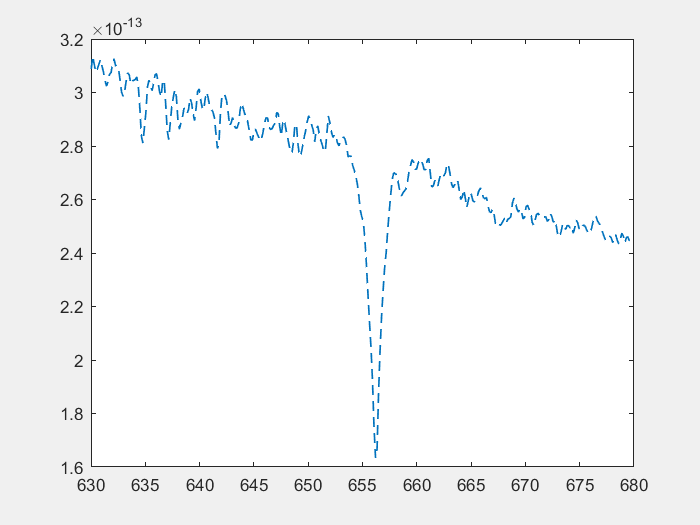

close all
clear variables 

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/с

spectra = importdata ("spectra.csv");
lambdaStart = importdata ("lambda_start.csv");
lambdaDelta = importdata ("lambda_delta.csv");
starNames = importdata ("star_names.csv");

numberOfObservations = size (spectra, 1);
numberOfStars = size (starNames, 1);
lambdaEnd = lambdaStart + (numberOfObservations - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

figure1 = figure;
set (figure1, 'Visible', 'on');

[minIs, indexsMinElements] = min (spectra);
lambdaHa = lambda (indexsMinElements);

z = (lambdaHa/lambdaPr) - 1;
speed = z * speedOfLight;
    
for cycleCount = 1 : numberOfStars
    if z (cycleCount) > 0
        plot (lambda, spectra(:, cycleCount), "-", 'LineWidth', 3);
    else
        plot (lambda, spectra(:, cycleCount), "--", 'LineWidth', 1);
    end
    hold on;
end


hold off;

movaway = starNames (z > 0);

title ("Спектры звезд")
xlabel ("Длина волны, нм");
ylabel (['Интенсивность, эрг/см^2/c', char(198)]);
grid on;

legend (starNames);


text (lambdaStart + 20, max(max (spectra)), ["Холодаева Элина", 'Б01-001']);
saveas (figure1, "I_lambda.png");



